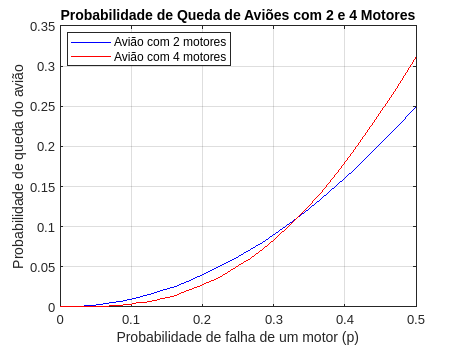

% Defina um vetor de valores de p
p_values = logspace(-3, log10(0.5), 100);

% Calcule as probabilidades de queda para aviões com 2 e 4 motores
prob_2_engines = p_values.^2;
prob_4_engines = (4 * p_values.^3 .* (1 - p_values)) + p_values.^4;

% Crie um gráfico
plot(p_values, prob_2_engines, 'b', 'DisplayName', 'Avião com 2 motores');
hold on;
plot(p_values, prob_4_engines, 'r', 'DisplayName', 'Avião com 4 motores');
xlabel('Probabilidade de falha de um motor (p)');
ylabel('Probabilidade de queda do avião');
legend('Location', 'Best');
title('Probabilidade de Queda de Aviões com 2 e 4 Motores');
grid on;

% Mostrar o gráfico
hold off;